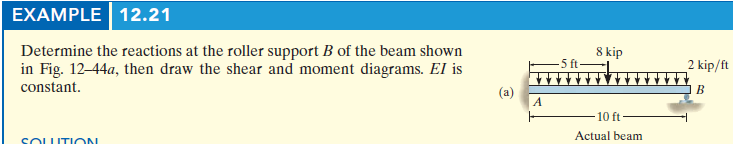

# beam

u = symunit;
b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'moment', 'Ma', 0);
b = b.add('reaction', 'force', 'Rb', 10*u.ft);
b = b.add('applied', 'force', -8*u.kip, 5*u.ft);
b = b.add('distributed', 'force', -2*u.kip/u.ft, [0 10]*u.ft);
b.L = 10*u.ft;

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x^{2}\,\left(x^{2}-36\,x\,\mathrm{ft}+240\,{\mathrm{ft}}^{2}\right)}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ \frac{\left(x-10\,\mathrm{ft}\right)\,\left(-x^{3}+10\,x^{2}\,\mathrm{ft}+100\,x\,{\mathrm{ft}}^{2}-200\,{\mathrm{ft}}^{3}\right)}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }5\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(x^{2}-27\,x\,\mathrm{ft}+120\,{\mathrm{ft}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ -\frac{x^{3}-15\,x^{2}\,\mathrm{ft}+300\,{\mathrm{ft}}^{3}}{3\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }5\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\left(x^{2}-18\,x\,\mathrm{ft}+40\,{\mathrm{ft}}^{2}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ -x\,\left(x-10\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }5\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -2\,\left(x-9\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 5\,\mathrm{ft}\\ -2\,\left(x-5\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }5\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = -2\,\frac{\mathrm{kip}}{\mathrm{ft}}$$

addvar(y);

# reactions

Ra = r.Ra %#ok

$$Ra = 18\,\mathrm{kip}$$

Ma = r.Ma %#ok

$$Ma = 40\,\mathrm{ft}\,\mathrm{kip}$$

Rb = r.Rb %#ok

$$Rb = 10\,\mathrm{kip}$$

clear Ra Ma Rb;

# shear and moment diagrams

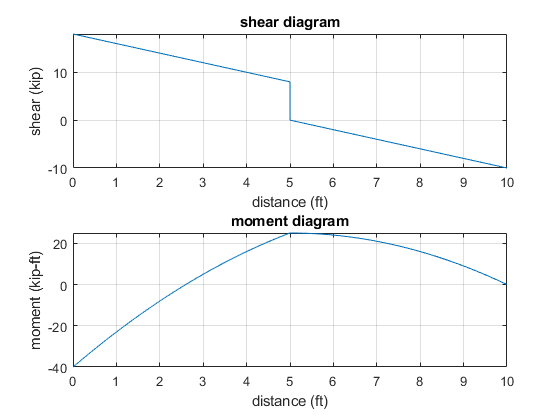

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});